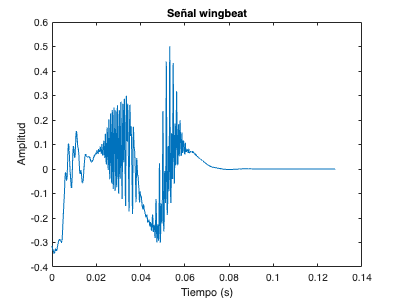

clear, clc, close all

% Carga de archivo de audio 
[datos, fs] = audioread("aedes_male/120502_f0051_m1056.40.wav");
datos = datos(:,1); % Obteniendo el primer canal 

% aedes_female/120501_f0002_m1096.90.wav
%%Señales interesantes 
% "aedes_female/120501_f0005_m1199.67.wav" Señal de ejemplo exposicion 
% aedes_male/120503_f0003_m1118.10.wav
% aedes_male/120510_f0128_m0354.36.wav
% stigma_female/120719_f0112_m1314.17.wav
%"tarsalis_male/120524_f0135_m0363.41.wav" error 
% aedes_female/120527_f0141_m0804.89.wav    error 
% aedes_female/120527_f0148_m0971.30.wav    error 
% "aedes_female/duplicado_2_120502_f0036_m0652.11.wav"
% aedes_male/120502_f0051_m1056.40.wav
% tarsalis_male/120503_f0012_m1396.50.wav
% quinx_female/120504_f0061_m1315.76.wav
% aedes_male/120523_f0118_m1333.59.wav Presenta error en la estimación de la frecuencia fundamental 
% 120506_f0161_m1215.36.wav
% stigma_male/120619_f0060_m1235.21.wav señal con ruido 
% stigma_male/120619_f0064_m1352.23.wav

N = length(datos);   

cent = N/2; 
liminf = cent + 0.5 - 1024; 
limsup = cent - 0.5 + 1024;

datos1 = datos(liminf:limsup);      % Señal recortada 
N1 = length(datos1);
datos2 = datos1(175:end-177);
N2 = length(datos2);

datos1 = wdenoise(datos1,7, ...
    Wavelet='sym5', ...
    DenoisingMethod='UniversalThreshold', ...
    ThresholdRule='Hard', ...
    NoiseEstimate='LevelDependent');

tiempo = (0:N1-1).*1/fs;

% Grafica de la señal 
figure('Position', [100, 100, 400, 300]);
plot(tiempo,datos1)
title('Señal wingbeat')
xlabel('Tiempo (s)')
ylabel('Amplitud')
%xlim([0.015 0.127])
grid off

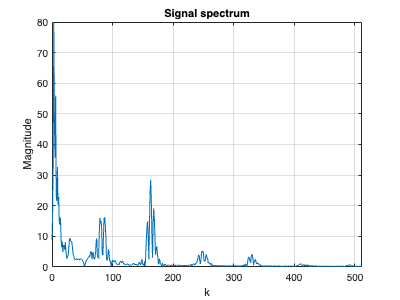

% Contenido espectral de la señal  

ft = fft(datos1);
k  = (0:length(ft)-1);
plot(k, abs(ft))
title('Signal spectrum')
xlabel('k')
ylabel('Magnitude')
xlim([0,length(ft)/4])
grid on

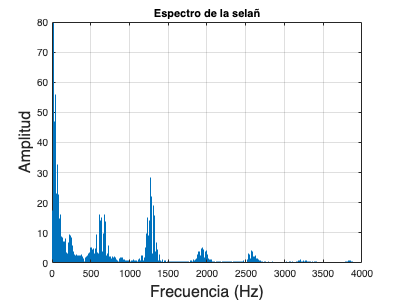

% Espectro vs frecuencia 

f  = (0:length(ft)-1).*fs/length(ft);
stem(f, abs(ft),'Marker',"none")
title('Espectro de la selañ')
xlabel('Frecuencia (Hz)','FontSize',16)
ylabel('Amplitud','FontSize',16)
xlim([0,fs/4])
grid on

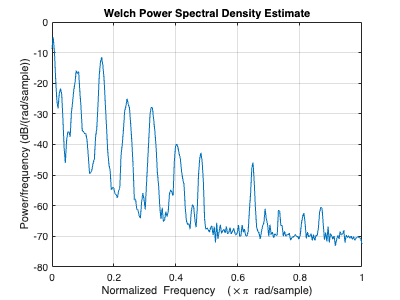

pwelch(datos1);

%%Análisis armónico 
y = abs(ft);
y1 = 40;
y2 = 80;
[mx0,ind0] = max(y(y1:y2));
value_f0   = mx0;                  % Magnitud de la frecuencia fundamental 
frec_fundamental = f(ind0+y1-1)    % El -1 es para cuadrar los indices 

frec_fundamental = 617.1875

f0 = pitch(datos1,fs,Range=[100,1600],WindowLength=2048,OverlapLength=0,Method="CEP")

f0 = 615.3846

b = median(f0);
indx_f = find(f>=(b-50) & f<=(b+50));
[mx01,ind01] = max(y(indx_f));
w0 = f(ind01+indx_f(1)-1)  % Frecuencia fundamental. El -1 es para cuadrar los indices 

w0 = 617.1875

indx_f2      = find(f>=(2*w0-80) & f<=(2*w0+80));
[mx02,ind02] = max(y(indx_f2));
w1           = f(ind02+indx_f2(1)-1);

% Armónicos 
[ampwk,wk]   = armonic(y,f,w0,8)

ampwk =    16.2156   28.4950    4.7197    3.2540    0.5055    0.3145    0.2222    0.2152


wk = 1.0e+03 *

    0.6797    1.2734    1.9297    2.5391    3.1562    3.7734    4.3906    4.9219


inharm(wk)

ans = 0.5009

[ts1,ts2,ts3] = tristimulus(ampwk)

ts1 = 0.3006

ts2 = 0.6761

ts3 = 0.0233

spIrregularity(ampwk)

ans = 20.5803

spIrremodif(ampwk)

ans = 0.6549

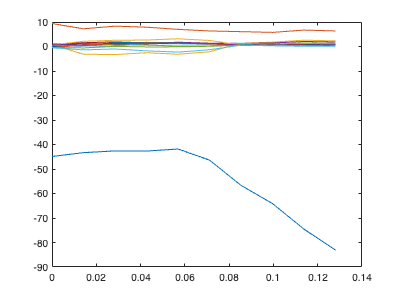

% Transformada corta de Fourier 
len_win = 256;                         % longitud de la ventana 
win = hann(len_win,"periodic");                % Ventana 
overlap = 0.5*len_win;                % Superposición de la ventana (recomendación 75% 0 50%)
nfft = 2*len_win;                      % Número de puntos fft (se recomienda que sea una potencia de 2)
[s, f, t] = spectrogram(datos1,win,overlap,nfft,fs,'yaxis');

% Coeficeintes cepstrales 
coef_mfcc = mfcc(s,fs,"LogEnergy","Ignore");
coef_mfcc(:,1);
vect_mfcc = [coef_mfcc(:,1); coef_mfcc(:,2); coef_mfcc(:,3); coef_mfcc(:,4);...
             coef_mfcc(:,5); coef_mfcc(:,6); coef_mfcc(:,7); coef_mfcc(:,8);...
             coef_mfcc(:,9); coef_mfcc(:,10)];


%xlabel([])
%ylabel([])
%xticks([]);
%yticks([]);
%colorbar off
%colormap(flipud(gray))

% setExtractorParameters(aFE,"mfcc",Name=Value)

len_win = round(0.03*fs); % longitud de la ventana
overlap = round(0.02*fs);

afe = audioFeatureExtractor(SampleRate=fs, ...
        Window=hamming(len_win,"periodic"),OverlapLength=overlap, ...
        zerocrossrate=true,shortTimeEnergy=true,pitch=true,mfcc=true);

idx = info(afe);
features = extract(afe,datos1);

t = linspace(0,size(datos1,1)/fs,size(features,1));
plot(t,features(:,idx.mfcc));

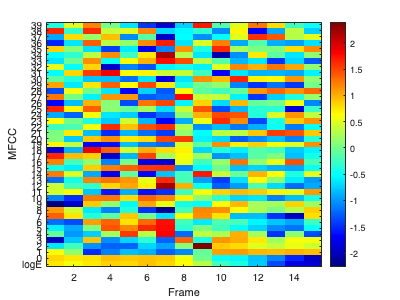

mfcc(s,fs,...
    "NumCoeffs",40,...
    "Window",hamming(128,"periodic"),...
    "OverlapLength",0.75*128,...
    "FFTLength",257);

# **Flujo espectral **

len_win = 1024;

[flux] = spectralFlux(datos1,fs,...
                      Window=hamming(2048,"periodic"),...
                      OverlapLength=0.75*len_win,...
                      Range=[100,fs/2])

flux = 0

flux = spectralFlux(datos1,fs,Range=[100,fs/2])

flux =          0
    0.0031
    0.0011
    0.0022
    0.0027
    0.0009
    0.0018
    0.0000
    0.0000
    0.0000


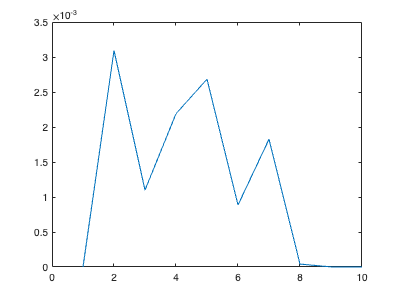

plot(flux)

rolloff = spectralRolloffPoint(datos1,fs,...
                      Window=hamming(2048,"periodic"),...
                      OverlapLength=0.75*len_win,...
                      Range=[100,fs/2])

rolloff = 1.8906e+03


rolloff_1 = max(rolloff)

rolloff_1 = 1.8906e+03

rolloff_2 = median(rolloff(rolloff<3000))

rolloff_2 = 1.8906e+03

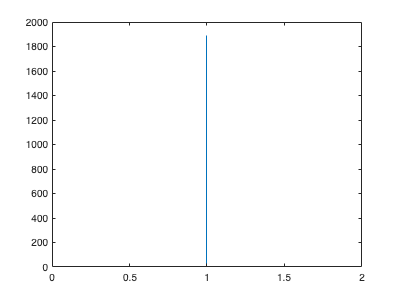


%%Threshold=0.85,...
stem(rolloff,'Marker','none')

flatness1 = spectralFlatness(datos1,fs,...
                      Window=hamming(len_win,"periodic"),...
                      OverlapLength=0.75*len_win,...
                      Range=[100,fs/2])

flatness1 =     0.0012
    0.0003
    0.0011
    0.0118
    0.1198


[flat,alpha]=flatness(y)

flat = -5.6836

alpha = 0.0947

mean(flatness1)

ans = 0.0268

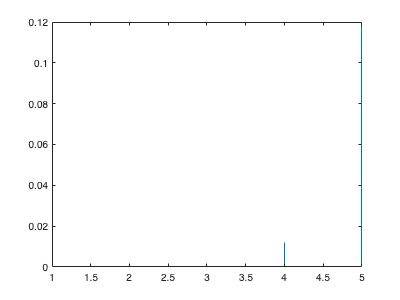

stem(flatness1,'Marker','none')

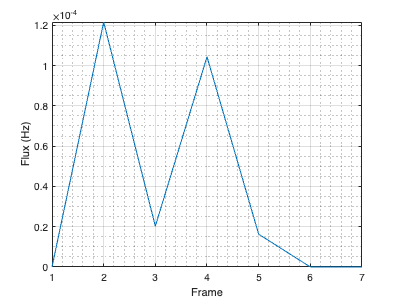

len_win = 512;
[s,cf,t] = melSpectrogram(datos1,fs,...
                          'Window',hamming(len_win,"periodic"),...
                          'OverlapLength',0.5*len_win,...
                          'FFTLength',2*len_win,...
                          'FrequencyRange',[100,fs/2]);

spectralFlux(s,cf)

rolloff12 = spectralRolloffPoint(s,cf)

rolloff12 = 1.0e+03 *

    1.3482
    1.3482
    1.3482
    1.3482
    1.2053
    0.3684
    0.7267


# Transformada corta de Fourier (Espectrograma)

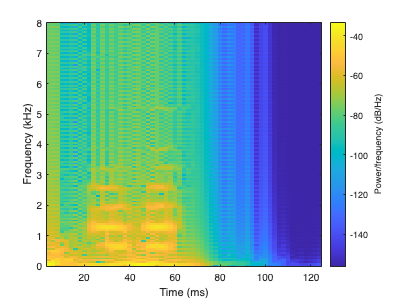

%Espetrograma 

len_win = 128; % longitud de la ventana 
win2 = kaiser(len_win,0.4);
win = hamming(len_win, "periodic");     % Ventana 
overlap = 0.75*len_win;                % Superposición de la ventana (recomendación 75% 0 50%)
nfft = 2*len_win;                      % Número de puntos fft (se recomienda que sea una potencia de 2)
spectrogram(datos1,win2,overlap,nfft,fs,'yaxis');

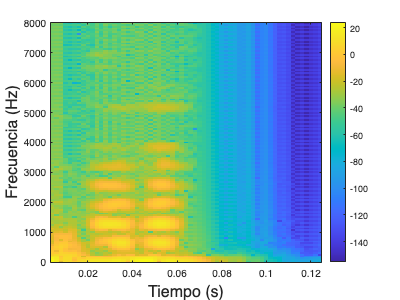

[s, f, t] = spectrogram(datos1,win,overlap,nfft,fs,'yaxis');

% Convertir amplitid a decibeles
s_dB = 20*log10(abs(s));

% Grafica de espectrograma
sp_img = imagesc(t,f,s_dB);

% Convertir la imagen a escala de grises y normalizar los valores a un rango entre 0 y 1
%gray_image = 1 - mat2gray(sp_img);

% Mostrar la imagen en escala de grises


% Matriz de la imagen 
%img = get(sp_img,'CData');

% Convertir imagen en escala de grises 
%gray_img = im2gray(img);

%J = imcomplement(gray_img);
%imshow(J)
set(gca, 'YDir', 'normal');
xlabel('Tiempo (s)','FontSize',16);
ylabel('Frecuencia (Hz)','FontSize',16)
%xlim auto
%title('Spectrogram')
%xticks([]);
%yticks([]);
%colormap(flipud(gray))

colorbar

# Melspectrogram

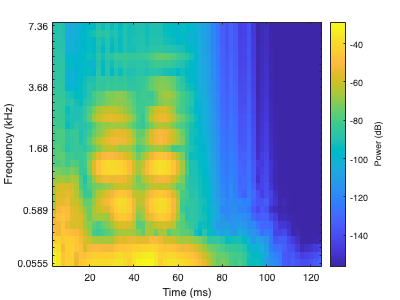

melSpectrogram(datos1,fs,...
               'Window',hamming(128, "periodic"),...
               'OverlapLength',0.75*128, ...
               'FFTLength',2*128);


% Tamaño de la imagen
%imaSize = [80, 80];
% Posición de la figura sin margen
%set(gca, 'Position', [0 0 1 1]);
%set(gca, 'YDir', 'normal');
%set(gcf, 'Position', [0, 0, imaSize]);

%xticks([]);
%yticks([]);
% flipud invierte la escala de grises de blanco a negro 
%colormap(gray)
%axis off;  



## Transformada wavelet continua

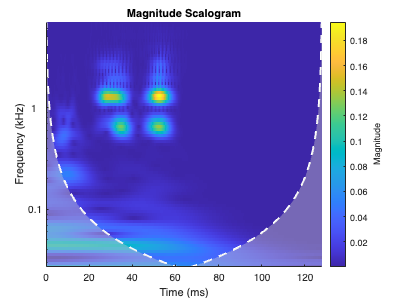

%Escalograma 
cwt(datos1,'morse',fs)

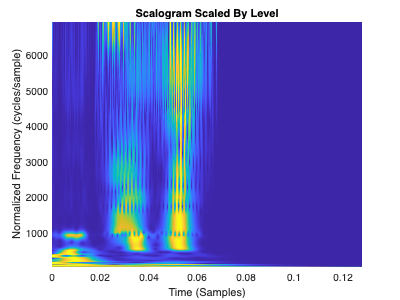


[cfs,frq] = cwt(datos1,'morse',fs);

tmp1 = abs(cfs);
t1 = size(tmp1,2);
tmp1 = tmp1';
minv = min(tmp1);
tmp1 = (tmp1-minv(ones(1,t1),:));

maxv = max(tmp1);
maxvArray = maxv(ones(1,t1),:);
indx = maxvArray<eps;
tmp1 = 240*(tmp1./maxvArray);
tmp2 = 1+fix(tmp1);
tmp2(indx) = 1;
tmp2 = tmp2';

t = (0:length(datos1)-1) / fs;
pcolor(t,frq,tmp2)
shading interp
xlabel("Time (Samples)")
ylabel("Normalized Frequency (cycles/sample)")
title("Scalogram Scaled By Level")

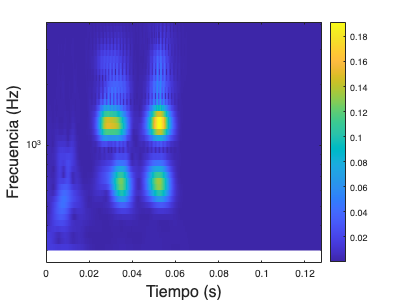

[cfs,frq] = cwt(datos1,'morse',fs, FrequencyLimits=[300 4048]);

% Vector de tiempos 
tiempo = (0:N1-1)/fs;

% Grafica de espectrograma
imagesc(tiempo,frq,abs(cfs));
set(gca, 'YDir', 'normal',"YScale","log");
xlabel('Tiempo (s)','FontSize',16);
ylabel('Frecuencia (Hz)','FontSize',16);
%xticks([]);
%yticks([]);
% flipud invierte la escala de grises de blanco a negro 
%colormap(flipud(gray))
colorbar

% Visualización del espectrograma


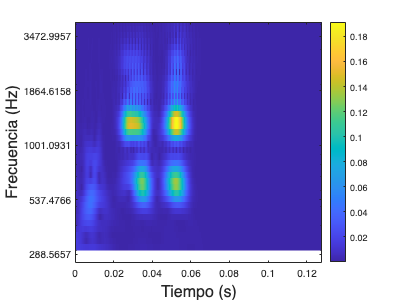

x = datos1;
[minf,maxf] = cwtfreqbounds(numel(x),8000);
numfreq = 10;
freq = logspace(log10(minf),log10(maxf),numfreq);
AX = gca;
AX.YTickLabelMode = "auto";
AX.YTick = freq;

## Transformada wavelet discreta

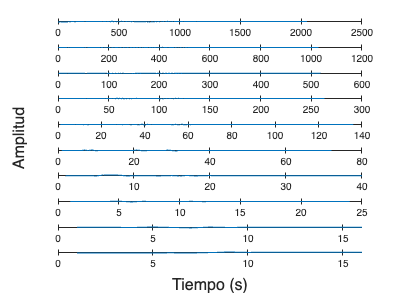

level = 8;

fig = tiledlayout(level+2, 1, 'TileSpacing', 'Compact');
[cA, cD] = dwt(datos1,'db5');

nexttile
plot(datos1)

nexttile
plot(cD)

for i = 1:level-1  
    nexttile    
    [cA, cD] = dwt(cA,'db5');
    plot(cD);
end 

nexttile 
plot(cA)

xlabel(fig, 'Tiempo (s)','FontSize',16);
ylabel(fig, 'Amplitud','FontSize',16);

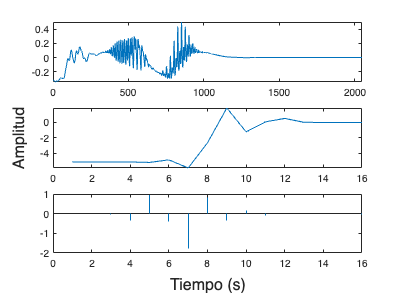

level = 8;

fig = tiledlayout(3, 1, 'TileSpacing', 'Compact');
[cA, cD] = dwt(datos1,'db5');

nexttile
plot(datos1, 'Marker','none')
xlim([0, 2048])

for i = 1:level-1      
    [cA, cD] = dwt(cA,'db5');
end 

nexttile
plot(cA, 'Marker','none');

nexttile 
stem(cD, 'Marker','none')

xlabel(fig, 'Tiempo (s)','FontSize',16);
ylabel(fig, 'Amplitud','FontSize',16);

## Transformada Wavelet Packets

level = 8;
wname = 'sym5';
wpt = wpdec(datos1,level,wname); %Árbol de coefientes (ver documentación) 

wpt

 
Wavelet Packet Object Structure
Size of initial data :      [2048     1]
Order                :      2
Depth                :      8
Terminal nodes       :      [255  256  257  258  259  260  261  262  263  264  265  266  267  268  269  270 ...]
------------------------------------------------
Wavelet Name               :sym5
Low Decomposition filter   :[ 0.02733    0.02952   -0.03913     0.1994     0.7234      0.634     0.0166    -0.1753 ...]
High Decomposition filter  :[-0.01954    -0.0211     0.1753     0.0166     -0.634     0.7234    -0.1994   -0.03913 ...]
Low Reconstruction filter  :[ 0.01954    -0.0211    -0.1753     0.0166      0.634     0.7234     0.1994   -0.03913 ...]
High Reconstruction filter :[ 0.02733   -0.02952   -0.03913    -0.1994     0.7234     -0.634     0.0166     0.1753 ...]
------------------------------------------------
Entropy Name               :shannon
Entropy Parameter          :0
-------------------------------------------

% Identificar los nodos terminales
terminal_nodes = leaves(wpt);
% Mostrar los nodos terminales
disp('Nodos terminales:');

Nodos terminales:


disp(terminal_nodes);

   255
   256
   257
   258
   259
   260
   261
   262
   263
   264
   265
   266
   267
   268
   269
   270
   271
   272
   273
   274
   275
   276
   277
   278
   279
   280
   281
   282
   283
   284
   285
   286
   287
   288
   289
   290
   291
   292
   293
   294
   295
   296
   297
   298
   299
   300
   301
   302
   303
   304
   305
   306
   307
   308
   309
   310
   311
   312
   313
   314
   315
   316
   317
   318
   319
   320
   321
   322
   323
   324
   325
   326
   327
   328
   329
   330
   331
   332
   333
   334
   335
   336
   337
   338
   339
   340
   341
   342
   343
   344
   345
   346
   347
   348
   349
   350
   351
   352
   353
   354
   355
   356
   357
   358
   359
   360
   361
   362
   363
   364
   365
   366
   367
   368
   369
   370
   371
   372
   373
   374
   375
   376
   377
   378
   379
   380
   381
   382
   383
   384
   385
   386
   387
   388
   389
   390
   391
   392
   393
   394
   395
   396
   397

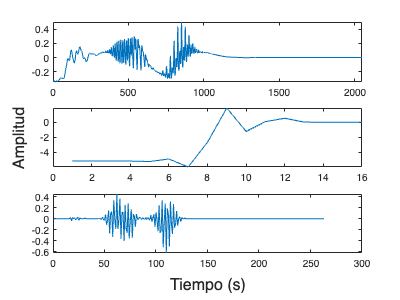


wpc = wpcoef(wpt,8);  % Retorna los cuefientes wavelet en el nodo indicado (ver wpt)  


plot(wpc)

wpt

 
Wavelet Packet Object Structure
Size of initial data :      [2048     1]
Order                :      2
Depth                :      8
Terminal nodes       :      [255  256  257  258  259  260  261  262  263  264  265  266  267  268  269  270 ...]
------------------------------------------------
Wavelet Name               :sym5
Low Decomposition filter   :[ 0.02733    0.02952   -0.03913     0.1994     0.7234      0.634     0.0166    -0.1753 ...]
High Decomposition filter  :[-0.01954    -0.0211     0.1753     0.0166     -0.634     0.7234    -0.1994   -0.03913 ...]
Low Reconstruction filter  :[ 0.01954    -0.0211    -0.1753     0.0166      0.634     0.7234     0.1994   -0.03913 ...]
High Reconstruction filter :[ 0.02733   -0.02952   -0.03913    -0.1994     0.7234     -0.634     0.0166     0.1753 ...]
------------------------------------------------
Entropy Name               :shannon
Entropy Parameter          :0
-------------------------------------------

%plot(wpt)

%[S,T,F] = wpspectrum(wpt,fs,'plot');
%colormap(gray)